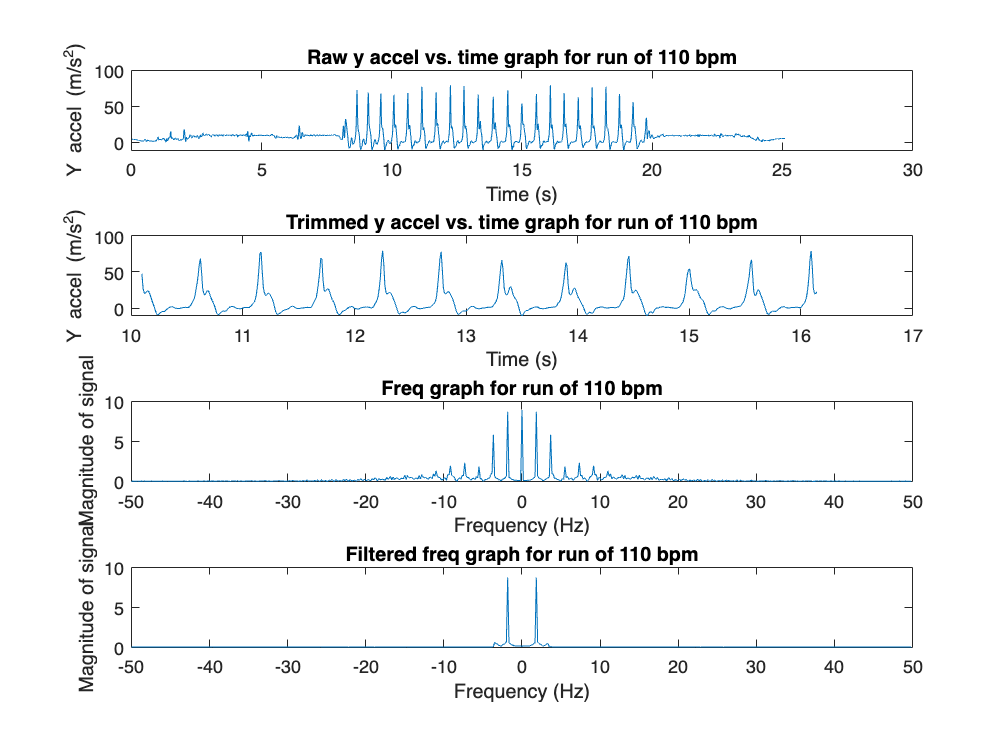

processData('110_bpm.csv', 110, 10, 16, false, true)

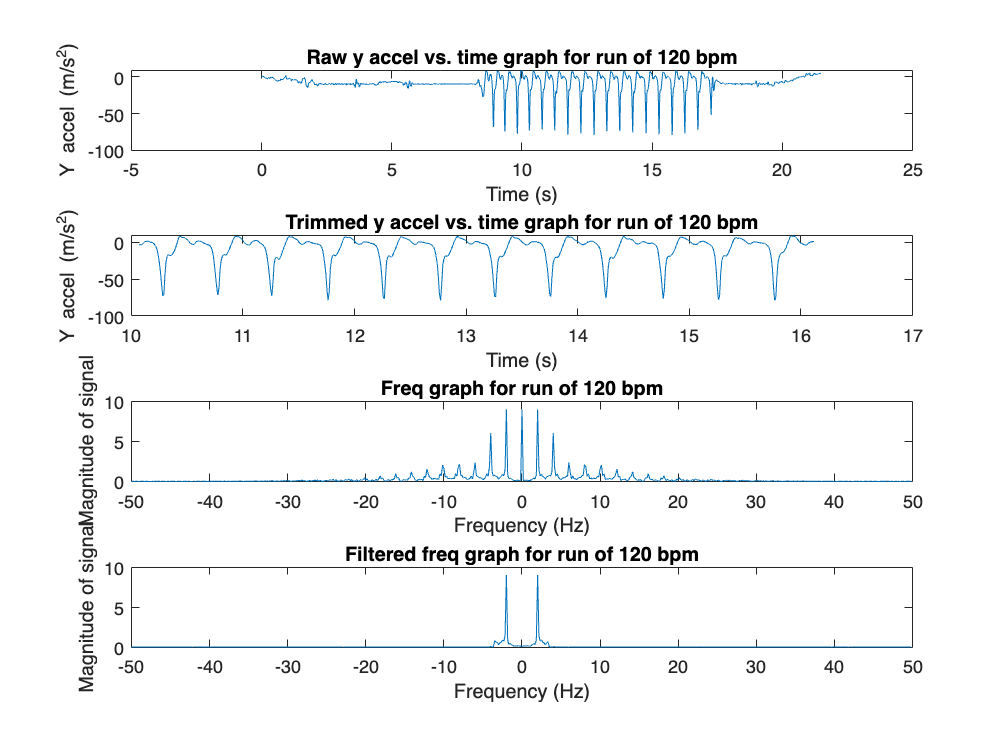

processData('120_bpm.csv', 120, 10, 16, false, true)

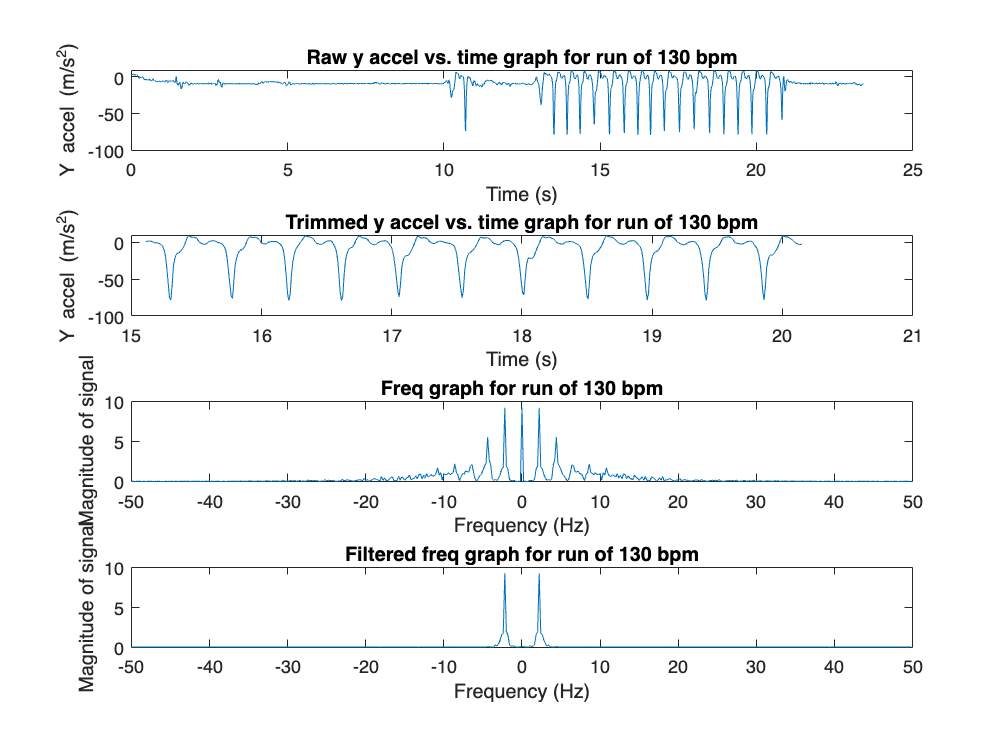

processData('130_bpm.csv', 130, 15, 20, false, true)

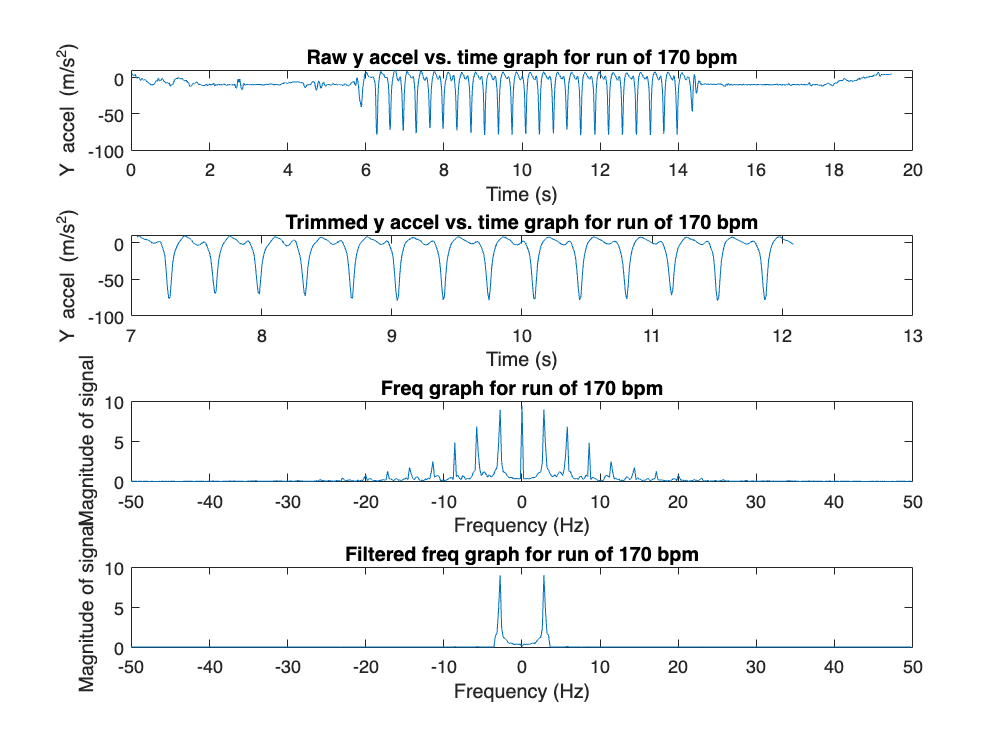

processData('170_bpm.csv', 170, 7, 12, false, true)

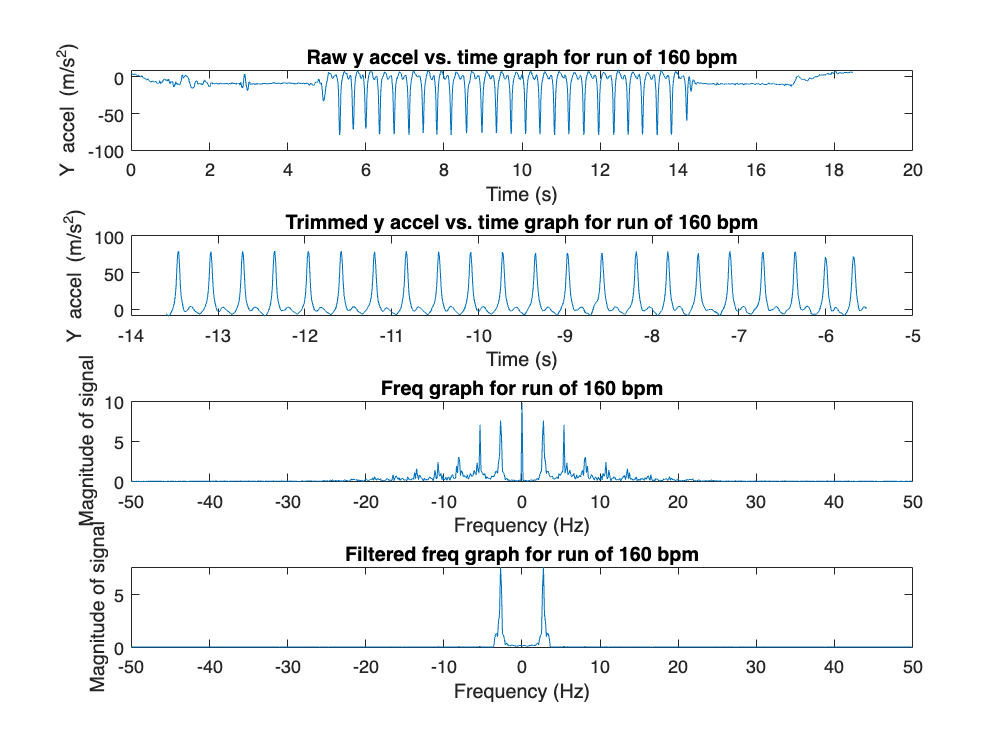

processData('160_bpm.csv', 160, 5.5, 13.5, true, true)

function plotData(csv_filename)
    raw_data = readtable(csv_filename);
    plot(raw_data.t, raw_data.a_y)
end

% todo get most prominent peak

function processData(csv_filename, known_bpm, t_start, t_end, isFlipped, showAll)
    clf;
    raw_data = readtable(csv_filename);
    t_trimmed = raw_data.t(t_start * 100:t_end * 100);
    a_y_trimmed = raw_data.a_y(t_start * 100:t_end * 100);
    if isFlipped
        t_trimmed = t_trimmed * -1;
        a_y_trimmed = a_y_trimmed * -1;
    end

    if showAll
        % plot raw data
        subplot(4,1,1);
        plot(raw_data.t, raw_data.a_y)
        xlabel("Time (s)")
        ylabel("Y accel (m/s^2)")
        title("Raw y accel vs. time graph for run of " + known_bpm + " bpm")
    end

    % plot trimmed data
    subplot(4,1,2);
    plot(t_trimmed, a_y_trimmed)
    xlabel("Time (s)")
    ylabel("Y accel (m/s^2)")
    title("Trimmed y accel vs. time graph for run of " + known_bpm + " bpm")
    
    if showAll
        % plot frequency graph without suppression
        subplot(4,1,3);
        make_freq_plot(a_y_trimmed, 100)
        title("Freq graph for run of " + known_bpm + " bpm")
    end

    % plot frequency graph, suppressed
    subplot(4,1,4);
    make_freq_plot_suppress(a_y_trimmed, 100)
    title("Filtered freq graph for run of " + known_bpm + " bpm")
end